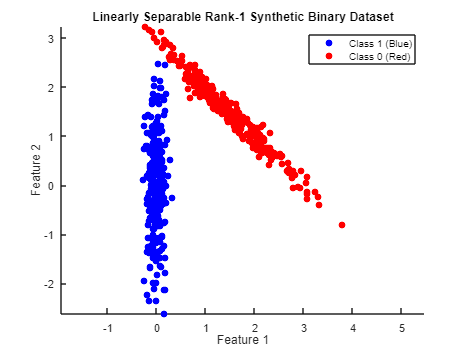

% Parameters
num_points = 600; % Total number of points
class1_angle = pi/2; % Principal direction for class 1 (45 degrees) pi\4
class2_angle = -pi/4; % Principal direction for class 0 (-30 degrees) -pi\6
noise_level = 0.1; % Small noise to spread points around the principal line 0.1
class_distance =1.5; % Distance between the classes to ensure separability 2

% Generate class 1 points
class1_t = randn(num_points/2, 1); % Parameter along the principal component
class1_x = class1_t * cos(class1_angle) + randn(num_points/2, 1) * noise_level; % Feature 1
class1_y = class1_t * sin(class1_angle) + randn(num_points/2, 1) * noise_level; % Feature 2
class1_labels = ones(num_points/2, 1); % Label = 1

% Generate class 0 points
class2_t = randn(num_points/2, 1); % Parameter along the principal component
class2_x = class2_t * cos(class2_angle) + randn(num_points/2, 1) * noise_level + class_distance; % Feature 1
class2_y = class2_t * sin(class2_angle) + randn(num_points/2, 1) * noise_level + class_distance; % Feature 2
class2_labels = zeros(num_points/2, 1); % Label = 0

% Combine the dataset
X = [class1_x, class1_y; class2_x, class2_y]; % Features
Y = [class1_labels; class2_labels]; % Labels

% Scatter plot of the dataset
figure;
scatter(class1_x, class1_y, 'b', 'filled'); hold on;
scatter(class2_x, class2_y, 'r', 'filled');
title('Linearly Separable Rank-1 Synthetic Binary Dataset');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1 (Blue)', 'Class 0 (Red)');
axis equal;


% Save to CSV if needed
dataset = [X, Y]

dataset =     0.0019    0.4458    1.0000
   -0.0428    0.6957    1.0000
   -0.0338   -0.4974    1.0000
    0.1107   -0.1650    1.0000
   -0.0713   -1.2828    1.0000
    0.1633   -2.6111    1.0000
    0.1377   -0.0639    1.0000
   -0.0622    0.0717    1.0000
    0.0898    0.4824    1.0000
   -0.1478   -0.1556    1.0000


csvwrite('toy_dataset12.csv', dataset);

disp('Linearly separable dataset created and saved as linearly_separable_rank1_dataset.csv');

Linearly separable dataset created and saved as linearly_separable_rank1_dataset.csv
